rng(3);
k = 3; % Number of GMM components
options = statset('MaxIter',1000);

Sigma = {'diagonal','full'}; % Options for covariance matrix type
nSigma = numel(Sigma);

SharedCovariance = {true,false}; % Indicator for identical or nonidentical covariance matrices
SCtext = {'true','false'};
nSC = numel(SharedCovariance);

d = 500; % Grid length
x1 = linspace(min(X(:,1))-2, max(X(:,1))+2, d);
x2 = linspace(min(X(:,2))-2, max(X(:,2))+2, d);
[x1grid,x2grid] = meshgrid(x1,x2);
X0 = [x1grid(:) x2grid(:)];



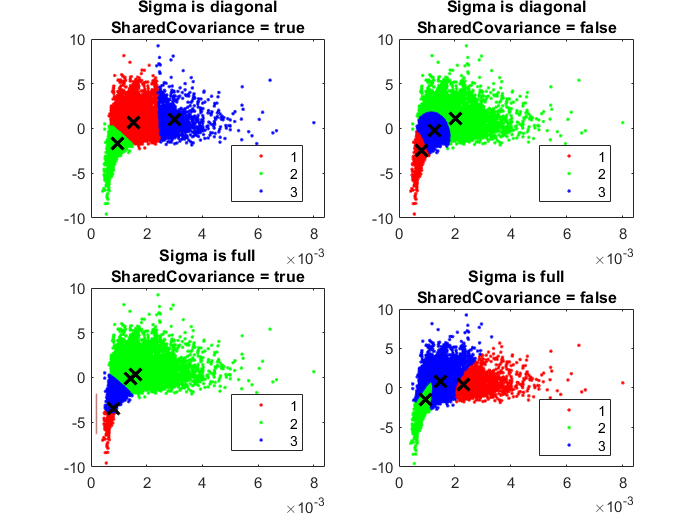

threshold = sqrt(chi2inv(0.99,2));
count = 1;
for i = 1:nSigma
    for j = 1:nSC
        gmfit = fitgmdist(X,k,'CovarianceType',Sigma{i}, ...
            'SharedCovariance',SharedCovariance{j},'Options',options); % Fitted GMM
        clusterX = cluster(gmfit,X); % Cluster index 
        mahalDist = mahal(gmfit,X0); % Distance from each grid point to each GMM component
        % Draw ellipsoids over each GMM component and show clustering result.
        subplot(2,2,count);
        h1 = gscatter(X(:,1),X(:,2),clusterX);
        hold on
            for m = 1:k
                idx = mahalDist(:,m)<=threshold;
                Color = h1(m).Color*0.75 - 0.5*(h1(m).Color - 1);
                h2 = plot(X0(idx,1),X0(idx,2),'.','Color',Color,'MarkerSize',1);
                uistack(h2,'bottom');
            end    
        plot(gmfit.mu(:,1),gmfit.mu(:,2),'kx','LineWidth',2,'MarkerSize',10)
        title(sprintf('Sigma is %s\nSharedCovariance = %s',Sigma{i},SCtext{j}),'FontSize',8)
        legend(h1,{'1','2','3'})
        hold off
        count = count + 1;
    end
end